% Variieren der Hyperparameter sigmaF, sigmaN, l und berechnen der logLikelihood
close
clear
clc
load trainingsdaten.mat

x = x(10 : 10:end,:);
y = y(10 : 10:end,1);
u = u(10 : 10:end,:);
dx = dx(10 : 10:end,1);
n = length(y);

**Variation aller Hyperparameter gleichzeitig**

%sigmaF = (logspace(0,3,100)).';
%sigmaN = (logspace(-2,0,100)).';
% l = (logspace(0,2,50)).';


sigmaF = (0.2:0.02:0.4).';
sigmaN = (0.3:0.02:0.5).';
l = (0.2:0.02:0.4).';
logLike = zeros(length(sigmaF),length(sigmaN),length(l));
for i = 1: length(sigmaF)
    for j = 1: length(sigmaN)
        for k = 1: length(l)
        K=CovMatrix(x,sigmaF(i),l(k));
        logLike(i,j,k)=logLikelihood_V1(y,K,sigmaN(j)); 
        end
    end
end

Finden des Maximums 

maxLik=max(logLike(~isinf(logLike)))

maxLik = 50.1786

%[sigmaFmax sigmaNmax lMax ] = find(lL_FNl == maxLik)
[r,c,v] = ind2sub(size(logLike),find(logLike == maxLik))

r = 11

c = 3

v = 8

sigmaFmax = sigmaF(r)

sigmaFmax = 0.4000

sigmaNmax = sigmaN(c)

sigmaNmax = 0.3400

lMax = l(v)

lMax = 0.3400


% save('hyperparameter','logLike','sigmaF','sigmaN','l','sigmaFmax','sigmaNmax','lMax')

Plotten der Höhenlinien

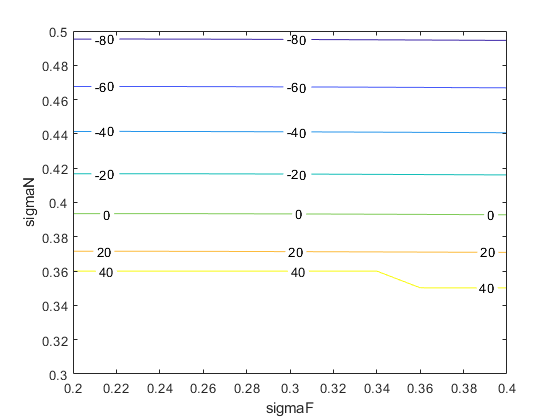

% l fixiert
[x,y] = meshgrid(sigmaF,sigmaN);
x =x.';
y = y.';
logLike_lmax = logLike(:,:,v);

figure(1)
contour(x,y,logLike_lmax,'ShowText','on')
xlabel('sigmaF')
ylabel('sigmaN')

**Hyperparameter am Optimum festhalten und einen variieren**

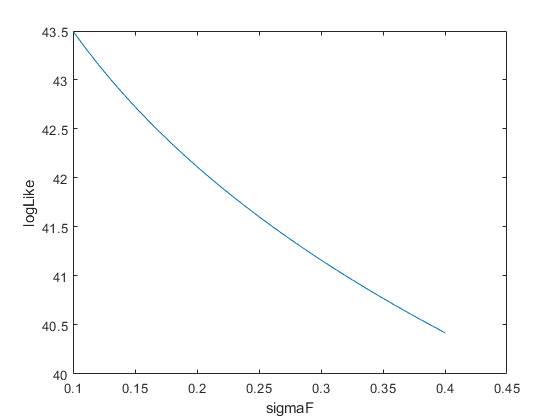

% sigma F varrieren
sigmaF = (0.1:0.01:0.4).';
sigmaN = 0.35;
l = 0.34;
logLike_sF = zeros(size(sigmaF));
for i = 1: length(sigmaF)
        K=CovMatrix([u,x],sigmaF(i),l);
        logLike_sF(i)=logLikelihood_V1(dx,K,sigmaN);
end
figure(2)
plot (sigmaF, logLike_sF)
xlabel('sigmaF')
ylabel('logLike')

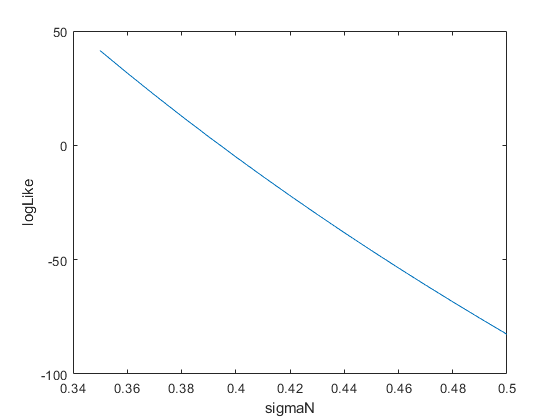

% sigma N varrieren
sigmaF = 0.3;
sigmaN = (0.3:0.01:0.5).';
l = 0.4;
logLike_sN = zeros(size(sigmaN));
for i = 1: length(sigmaN)
        K=CovMatrix([u,x],sigmaF,l);
        logLike_sN(i)=logLikelihood_V1(dx,K,sigmaN(i));
end
figure(3)
plot (sigmaN, logLike_sN)
xlabel('sigmaN')
ylabel('logLike')

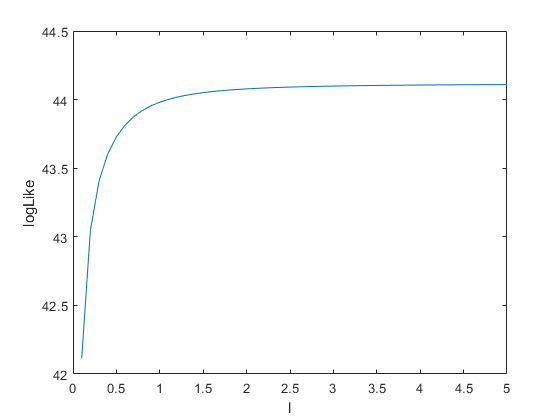

% l varrieren
sigmaF = 0.1;
sigmaN = 0.35;
l =(0.1:0.1:5).';
logLike_l = zeros(size(l));
for i = 1: length(l)
        K=CovMatrix([u,x],sigmaF,l(i));
        logLike_l(i)=logLikelihood_V1(dx,K,sigmaN);
end
figure(4)
plot (l, logLike_l)
xlabel('l')
ylabel('logLike')